defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 2 - ISCs']);

crens = loadCellStructs('.\Data\Crenations\P7_8\*.mat')

crens = 1×8 struct array with fields:
    name
    locs
    pks
    stdStart
    stdEnd
    areas
    meanPlot
    imgSTD
    stdMP
    crenationImg
    scalingFactor


baseline = [0 600-2*60];
MRS2500 = [720 20*60];
freqs = []; areas = [];
for i = 1:size(crens,2)
    freqs(i,:) = [size(crens(i).locs(crens(i).locs < baseline(2)),1)/8 ...
        size(crens(i).locs(crens(i).locs > MRS2500(1)),1)/8];
    areas(i,:) = [nanmean(crens(i).areas(crens(i).locs < baseline(2)),1) ... 
        nanmean(crens(i).areas(crens(i).locs > MRS2500(1)),1) ];
end


figure;
h = compare2P(freqs(:,1),freqs(:,2),{'Baseline','MRS2500'},'Crenations per minute',[3 2],[5 12]);

    0.0020



xtickangle(45);
ylim([0 4]);
figQuality(gcf,gca,[1.25 1.5]);

figure;
h1 = compare2P(areas(:,1),areas(:,2),{'Baseline','MRS2500'},'Crenation area ',[3 2],[5 12]);

    0.0098



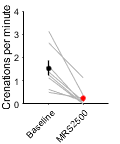

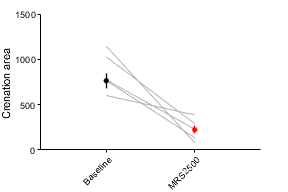

figQuality(gcf,gca,[3 2]);
ylim([0 1500])
xtickangle(45)
handleTheSubplot({h,h1},[1 2]);

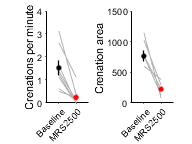

figQuality(gcf,gca,[2 1.5])
export_fig('.\EPS Panels\CrenationsFreq_new.eps')

fnum = 3;
fileList = loadFileList('.\Data\Crenations\P7_8\*.tif');
file = fileList{fnum};
baseimg = loadTif(file,16);
baseimg = mean(baseimg,3)

baseimg =    16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   41.3275   88.4450   77.8283   79.2992   74.3942   75.3958   75.4225   77.1025   78.4925   80.4450   82.2342   83.7742   84.5675   85.1442   85.8025   86.6567   87.3075   87.9683   88.4708   88.1975   85.7533   80.9192   76.0292   73.8508   74.2850   73.6650   68.5608   59.9717   52.2342   49.3633   52.3692   59.9192   68.3425   75.0500   79.7625   82.6183   84.2275   84.5067
   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   43.3275   91.8567   79.8367   81.1208   75.3983   76.3617   76.7925   79.0658   80.0433   81.1108   82.4608   84.0800   85.3275   86.0167   86.2292   86.6533   87.4908   88.7533   90.0092   90.1458   87.5067   82.2775   77.1558   75.0025   75.4000   74.3050   68.7208   59.6142   52.2767   51.2217   56.7375   64.7150   71.0975   74.9975   78.0783   80.1733   81.132

fileList = loadFileList('.\Data\Crenations\P7_8\*.mat');
file = fileList{fnum};
h = load(file);
crens = h.Crens;


[h,h1] = drawCrenations(crens.crenationImg(:,:,crens.locs < 480),crens.locs(crens.locs < 480),480,uint8(baseimg));
figure(h);
print('.\EPS Panels\baseline_crenations.pdf','-dpdf');

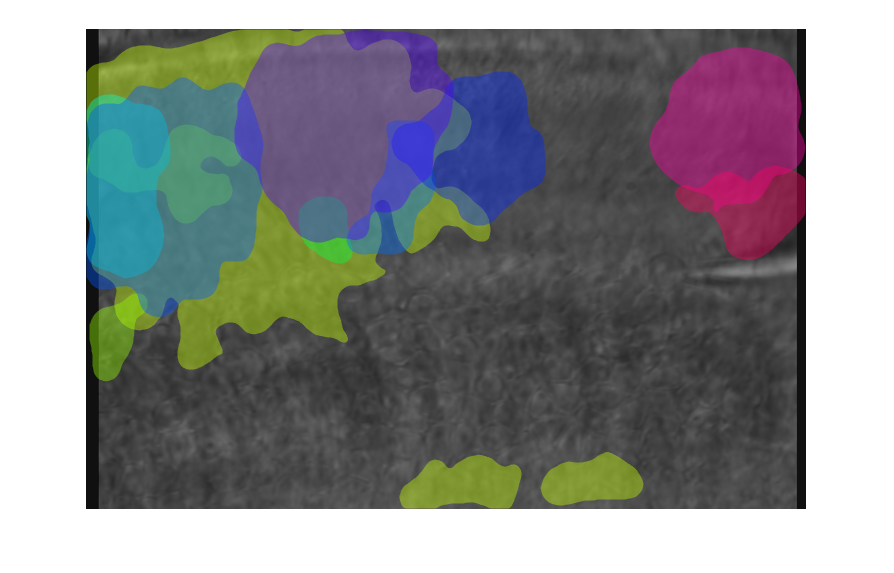

figure(h1);
figQuality(gcf,gca,[3 0.5]);
export_fig('.\EPS Panels\baseline_crenations_timeline.eps');

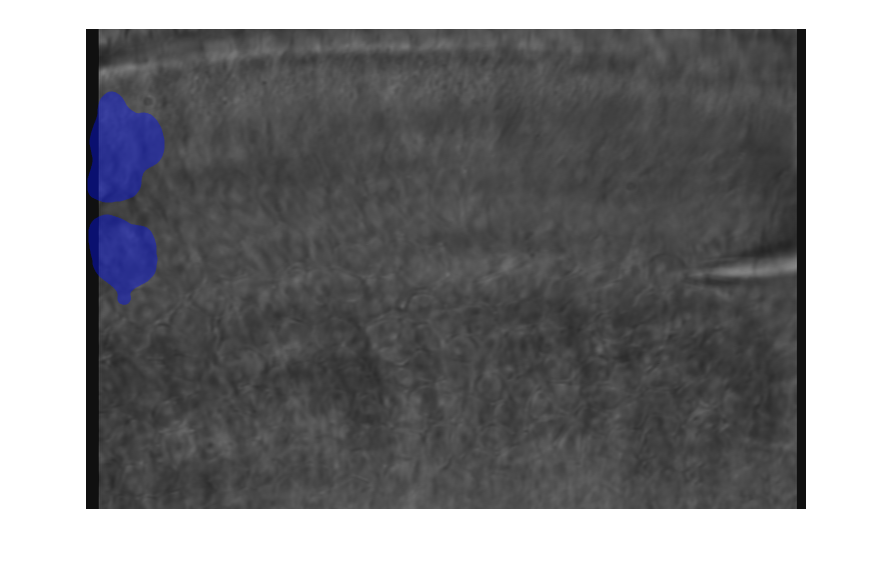


[h, h1] = drawCrenations(crens.crenationImg(:,:,crens.locs > 720),crens.locs(crens.locs > 720) -720,480,uint8(baseimg));
figure(h);
print('.\EPS Panels\MRS_crenations.pdf','-dpdf');

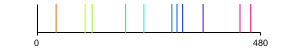

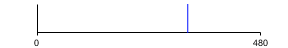

figure(h1);
figQuality(gcf,gca,[3 0.5]);
export_fig('.\EPS Panels\MRS_crenations_timeline.eps');